# TP2 - MAT6473

format compact;
format short e;

## Question 1

Le système d'edos initial pour la trajectoire du satellite est 


$$\frac{d^2x}{dt^2} = x+ 2\frac{dy}{dt} - (1-\mu)\left(\frac{x+\mu}{((x+\mu)^2 +y^2)^{3/2}}\right)-\mu\left(\frac{x-1+\mu}{((x-1+\mu)^2 +y^2)^{3/2}}\right)\\
\frac{d^2y}{dt^2} = y- 2\frac{dx}{dt} - (1-\mu)\left(\frac{y}{((x+\mu)^2 +y^2)^{3/2}}\right)-\mu\left(\frac{y}{((x-1+\mu)^2 +y^2)^{3/2}}\right)$$


où $\mu := m/M \approx 0.012155092$.

En prenant


$$z_1 = x\\
z_2 = y\\
z_3 = \frac{dx}{dt}\\
z_4 = \frac{dy}{dt}.$$


On obtient le système $\hat{z}' = \left(z_1,z_2,z_3,z_4 \right)^T = \hat{f}$


$$z_1' = z_3\\
z_2' = z_4\\
z_3' = z_1+ 2z_4 - (1-\mu)\left(\frac{z_1+\mu}{((z_1+\mu)^2 +z_2^2)^{3/2}}\right)-\mu\left(\frac{z_1-1+\mu}{((z_1-1+\mu)^2 +z_2^2)^{3/2}}\right)\\
z_4' = z_2- 2z_3 - (1-\mu)\left(\frac{z_2}{((z_1+\mu)^2 +z_2^2)^{3/2}}\right)-\mu\left(\frac{z_2}{((z_1-1+\mu)^2 +z_2^2)^{3/2}}\right)$$
    

avec les conditions initiales suivantes


$$(i) \ \ z_1(0) = -2.499999883 ; \  \  z_2(0) = 0 ; \  \ z_3(0) = 0; \ z_4(0) = 2.100046263\\
(ii) \ \ z_1(0) =0.952281734; \  \  z_2(0) = 0 ; \  \ z_3(0) = 0; \ z_4(0) = -0.957747254\\
(iii) \ \ z_1(0) = 3.147603117 ; \  \  z_2(0) = 0 ; \  \ z_3(0) = 0; \ z_4(0) = -3.07676285
$$


## Question 2

Fixons la tolérance sur la précision à $1\times {10}^{-6}$ pour calculer la période du satellite $T$ avec les différentes conditions initiales en utilisant Runge-Kutta-Fehlberg (RKF).

tol = 1e-6;
mu = 0.012155092;

### 2.1 Période $T_1$ avec condition initiale (i)

(2.1.a) Regardons la trajectoire sur l'intervalle de temps [0,13]. 

intervalle = [0,13];
z0 = [-2.499999883 ;0.0 ;0.0; 2.100046263];
[Z1,hList1,tList1] = rkf2023(@fTroisCorps,intervalle,z0,tol);

Graphique de la trajectoire

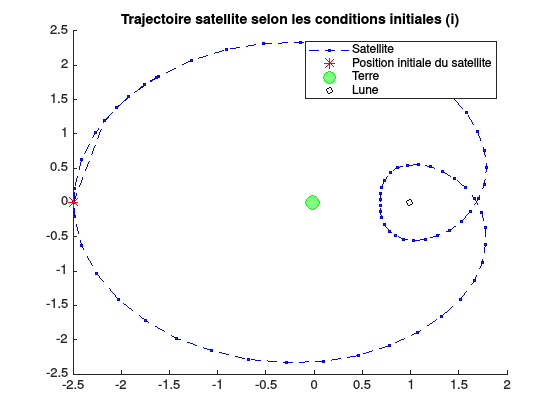

figure(1);
clf;
hold on;
plot(Z1(1,:),Z1(2,:),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
plot(z0(1),z0(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Terre','Lune')
title('Trajectoire satellite selon les conditions initiales (i)')

(2.1.b) Trouver la période.

s=size(Z1);
tot13= s(2);
listI = [0;0];
cand = z0;
candDist = z0-z0;
for i=2:tot13
    yp = Z1(2,i-1);
    yn = Z1(2,i);
    if(yp*yn < 0)
        listI(:,end+1) = zeros(2,1);
        listI(1,end) = i;
        listI(2,end) = mean([tList1(i-1),tList1(i)]);
        cand(:,end+1)  = zeros(4,1);
        cand(1,end) = mean([Z1(1,i-1),Z1(1,i)]);
        cand(2,end) = mean([yp,yn]);
        cand(3,end) = mean([Z1(3,i-1),Z1(3,i)]);
        cand(4,end) = mean([Z1(4,i-1),Z1(4,i)]);
        candDist(:,end+1) = cand(:,end)-z0;
    end
end
ss = size(listI);
totCand = ss(2);
for i =2:totCand
    if(norm(candDist(:,i)) < 1)
        T1 = listI(2,i)
        break;
    end
end

T1 =    1.2000e+01

(2.1.c) RKF avec le $t_f =T_1$.

intervalle = [0,T1];
z0 = [-2.499999883 ;0.0 ;0.0; 2.100046263];
[Z1,hList1,tList1] = rkf2023(@fTroisCorps,intervalle,z0,tol);

Graphique de la trajectoire

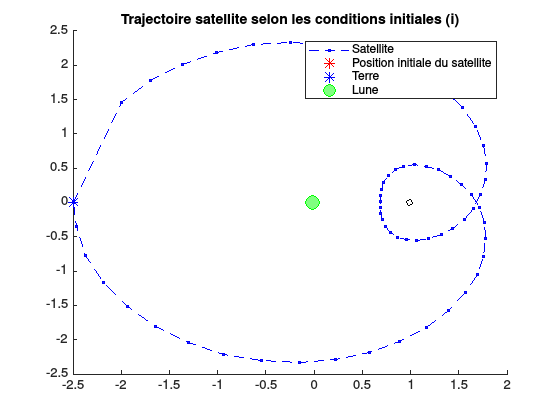

figure(1);
clf;
hold on;
plot(Z1(1,:),Z1(2,:),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
plot(z0(1),z0(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Z1(1,end),Z1(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Terre','Lune')
title('Trajectoire satellite selon les conditions initiales (i)')

### 2.2 Période $T_2$ avec condition initiale (2)

(2.2.a) Regardons la trajectoire sur l'intervalle de temps [0,13]. 

intervalle = [0,13];
z0 = [0.952281734 ;0.0 ;0.0; -0.957747254];
[Z2,hList2,tList2] = rkf2023(@fTroisCorps,intervalle,z0,tol);

Graphique de la trajectoire

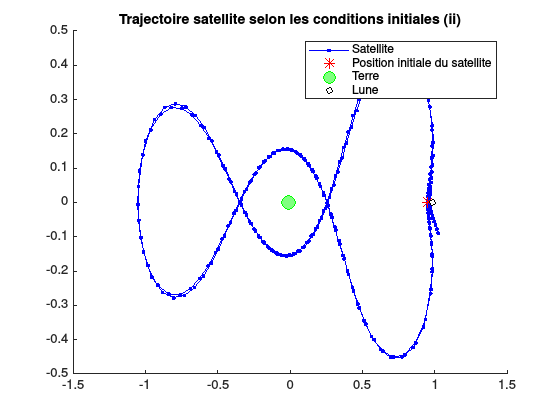

figure(2);
clf;
hold on;
plot(Z2(1,:),Z2(2,:),'b.-')
plot(z0(1),z0(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Terre','Lune')
title('Trajectoire satellite selon les conditions initiales (ii)')

(2.2.b) Trouver la période.

s=size(Z2);
tot13= s(2);
listI = [0;0];
cand = z0;
candDist = z0-z0;
for i=2:tot13
    yp = Z2(2,i-1);
    yn = Z2(2,i);
    if(yp*yn < 0)
        listI(:,end+1) = zeros(2,1);
        listI(1,end) = i;
        listI(2,end) = mean([tList2(i-1),tList2(i)]);
        cand(:,end+1)  = zeros(4,1);
        cand(1,end) = mean([Z2(1,i-1),Z2(1,i)]);
        cand(2,end) = mean([yp,yn]);
        cand(3,end) = mean([Z2(3,i-1),Z2(3,i)]);
        cand(4,end) = mean([Z2(4,i-1),Z2(4,i)]);
        candDist(:,end+1) = cand(:,end)-z0;
    end
end
ss = size(listI);
totCand = ss(2);
for i =2:totCand
    if(norm(candDist(:,i)) < 1)
        T2 = listI(2,i)
        break;
    end
end

T2 =    6.4484e+00

(2.2.c) RKF avec le $t_f =T_2$.

intervalle = [0,T2];
z0 = [0.952281734 ;0.0 ;0.0; -0.957747254];
[Z2,hList2,tList2] = rkf2023(@fTroisCorps,intervalle,z0,tol);

Graphique de la trajectoire

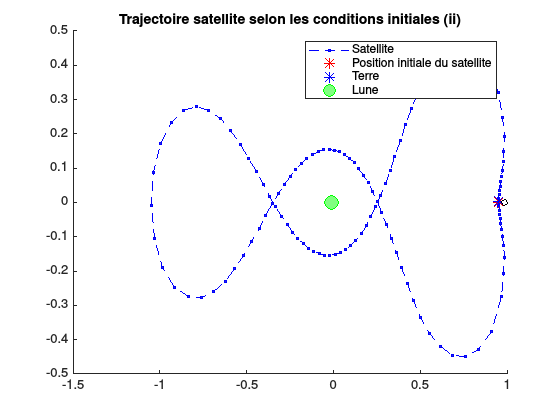

figure(1);
clf;
hold on;
plot(Z2(1,:),Z2(2,:),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
plot(z0(1),z0(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Z2(1,end),Z2(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Terre','Lune')
title('Trajectoire satellite selon les conditions initiales (ii)')

### 2.3 Période $T_3$ avec condition initiale (3)

(2.3.a) Regardons la trajectoire sur l'intervalle de temps [0,13]. 

intervalle = [0,13];
z0 = [3.147603117 ;0.0 ;0.0; -3.07676285];
[Z3,hList3,tList3] = rkf2023(@fTroisCorps,intervalle,z0,tol);

Graphique de la trajectoire

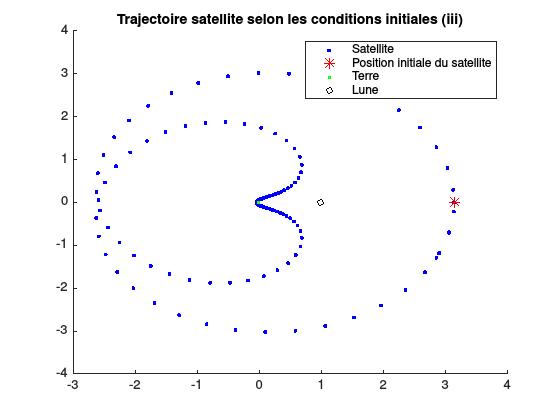

figure(3);
clf;
hold on;
plot(Z3(1,:),Z3(2,:),'b.')
plot(z0(1),z0(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',2,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Terre','Lune')
title('Trajectoire satellite selon les conditions initiales (iii)')

(2.3.b) Trouver la période.

s=size(Z3)

s =      4   148


tot13= s(2);
listI = [0;0];
cand = z0;
candDist = z0-z0;
for i=2:tot13
    yp = Z3(2,i-1);
    yn = Z3(2,i);
    if(yp*yn < 0)
        listI(:,end+1) = zeros(2,1);
        listI(1,end) = i;
        listI(2,end) = mean([tList3(i-1),tList3(i)]);
        cand(:,end+1)  = zeros(4,1);
        cand(1,end) = mean([Z3(1,i-1),Z3(1,i)]);
        cand(2,end) = mean([yp,yn]);
        cand(3,end) = mean([Z3(3,i-1),Z3(3,i)]);
        cand(4,end) = mean([Z3(4,i-1),Z3(4,i)]);
        candDist(:,end+1) = cand(:,end)-z0;
    end
end
candDist

candDist =             0  -5.7542e+00  -3.1838e+00  -5.7400e+00  -1.0784e-02
            0  -1.5221e-01  -1.3609e-03   2.6386e-02   4.2717e-02
            0   2.0585e-01   2.5296e-01  -3.3523e-01   4.3161e-02
            0   5.6179e+00  -5.8965e+00   5.5859e+00   1.1238e-02


ss = size(listI);
totCand = ss(2);
for i =2:totCand
    norm(candDist(:,i))
    if(norm(candDist(:,i)) < 1)
        T3 = listI(2,i)
        break;
    end
end

ans =    8.0459e+00

ans =    6.7059e+00

ans =    8.0164e+00

ans =    6.2692e-02

T3 =    1.2554e+01

(2.2.c) RKF avec le $t_f =T_3$.

intervalle = [0,T3];
z0 = [3.147603117 ;0.0 ;0.0; -3.07676285];
[Z3,hList3,tList3] = rkf2023(@fTroisCorps,intervalle,z0,tol);

Graphique de la trajectoire

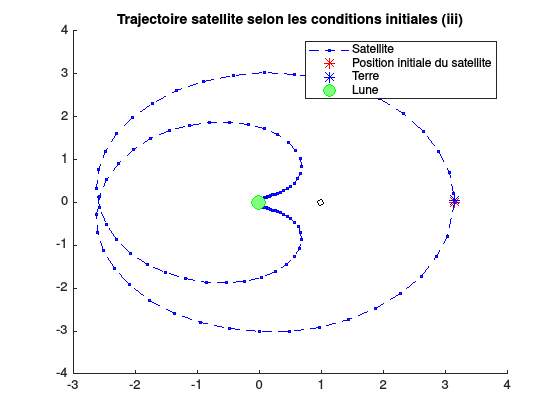

figure(1);
clf;
hold on;
plot(Z3(1,:),Z3(2,:),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
plot(z0(1),z0(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Z3(1,end),Z3(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Terre','Lune')
title('Trajectoire satellite selon les conditions initiales (iii)')